# Trajectory

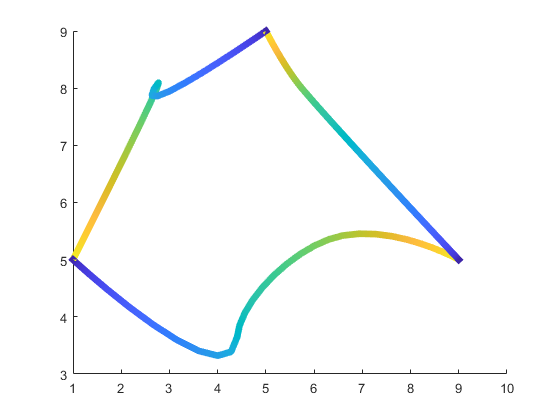

load("Drone1Traj.mat")
d1 = full_path;
load("Drone2Traj.mat")
d2 = full_path;
load("Drone3Traj.mat")
d3 = full_path;

% TODO: Add a collision check here
figure(1)
clf
patch([d1(:,2);nan],[d1(:,3);nan],[d1(:,4);nan],[d1(:,1)/max(d1(:,1));nan],'EdgeColor','interp','FaceColor','none','LineWidth',5);
hold on;
patch([d2(:,2);nan],[d2(:,3);nan],[d2(:,4);nan],[d2(:,1)/max(d2(:,1));nan],'EdgeColor','interp','FaceColor','none','LineWidth',5);
hold on;
patch([d3(:,2);nan],[d3(:,3);nan],[d3(:,4);nan],[d3(:,1)/max(d3(:,1));nan],'EdgeColor','interp','FaceColor','none','LineWidth',5);

# Costs

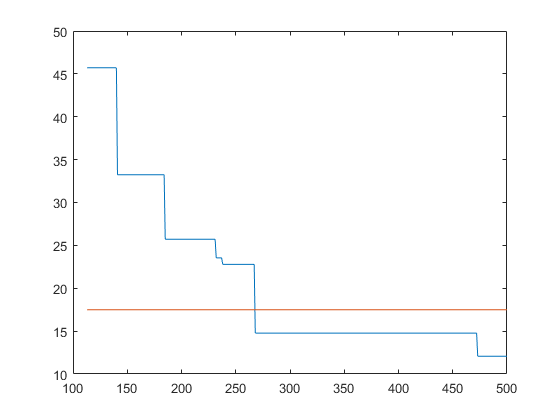

load("Drone1Costs.mat")
d1costs = iteration_costs;
load("Drone2Costs.mat")
d2costs = iteration_costs;
figure(2)
clf
plot(d1costs(:,1),d1costs(:,2))
hold on;
plot(d2costs(:,1),d2costs(:,2))

# Time

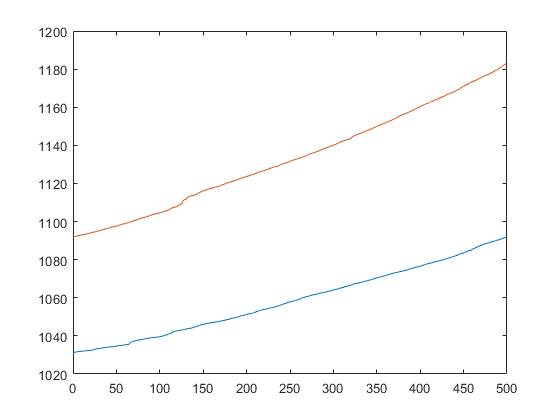

load("RRT1Times.mat")
d1times = iteration_times;
load("RRT2times.mat")
d2times = iteration_times;
figure(3)
clf
plot(d1times(:,1),d1times(:,2))
hold on;
plot(d2times(:,1),d2times(:,2))